# Examples for using the `space_data_equally` function.

Copyright © 2022 Tamas Kis

## Example #1: Making a data set equally spaced via linear interpolation.

Create a data set $\mathbf{y}$ vs. $\mathbf{x}$ where $\mathbf{x}$ stores $x$-values between (and including) 0 and 10, separated by different amounts, and where the $i^{\textrm{th}}$ $y$-value is given by $y_i =x_i^2 -5$.

x = [0,0.1,2,2.5,4.5,4.6,4.8,5.5,8,9.5,10];
y = x.^2-5;

Transform this data set using linear interpolation so that the data is equally spaced (with spacing $\Delta x=1$) in the independent variable.

[x_new,y_new] = space_data_equally(x,y,1);

Plot the original and equally spaced data on the same figure.

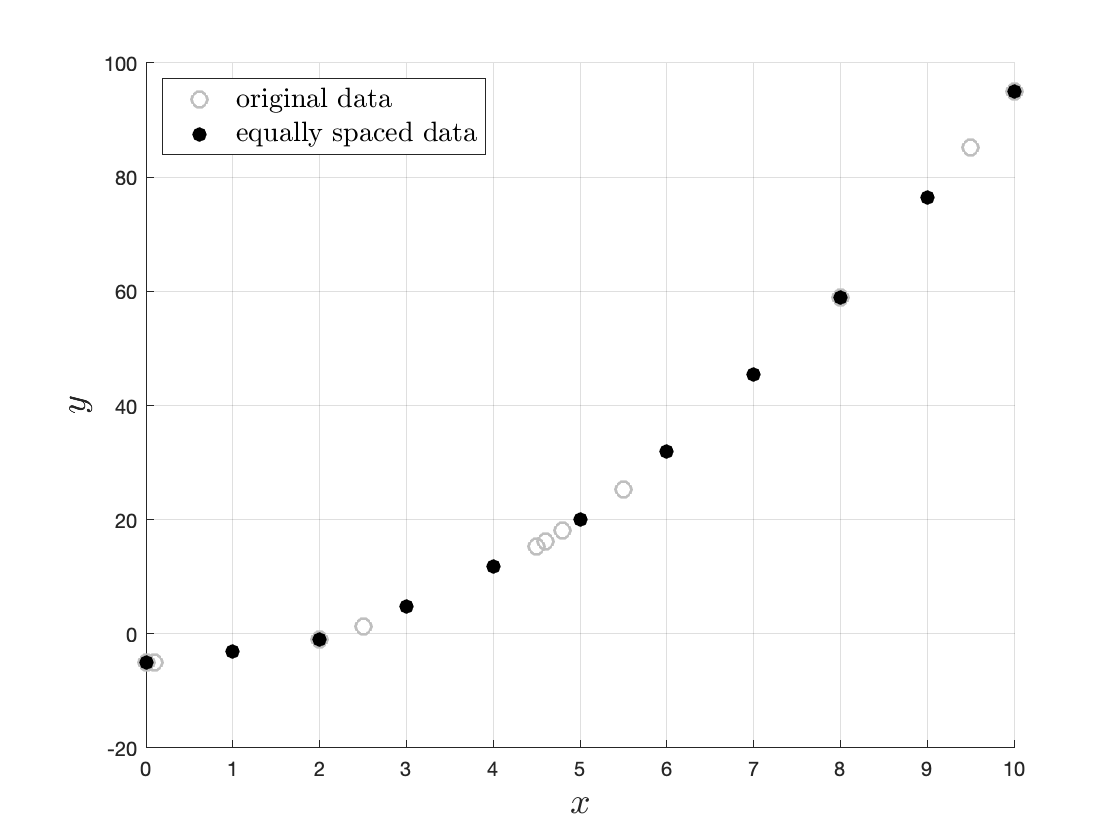

figure;
hold on;
plot(x,y,'o','MarkerSize',8,'LineWidth',1.5,'Color',[0.75,0.75,0.75]);
plot(x_new,y_new,'k.','MarkerSize',25,'LineWidth',1.5);
grid on;
hold off;
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
legend('original data','equally spaced data','Interpreter','latex',...
    'FontSize',14,'Location','northwest');

## Example #2: Making a data set equally spaced via spline interpolation.

Create a data set $\mathbf{y}$ vs. $\mathbf{x}$ where $\mathbf{x}$ stores $x$-values between (and including) 0 and 10, separated by different amounts, and where the $i^{\textrm{th}}$ $y$-value is given by $y_i =x_i^3 -5x_i^2 +10$.

x = [0,0.1,2,2.5,4.5,4.6,4.8,5.5,8,9.5,10];
y = x.^3-5*x.^2+10;

Transform this data set using linear interpolation so that the data is equally spaced (with spacing $\Delta x=0\ldotp 6$) in the independent variable.

[x_new,y_new] = space_data_equally(x,y,0.6,'spline');

Plot the original and equally spaced data on the same figure.

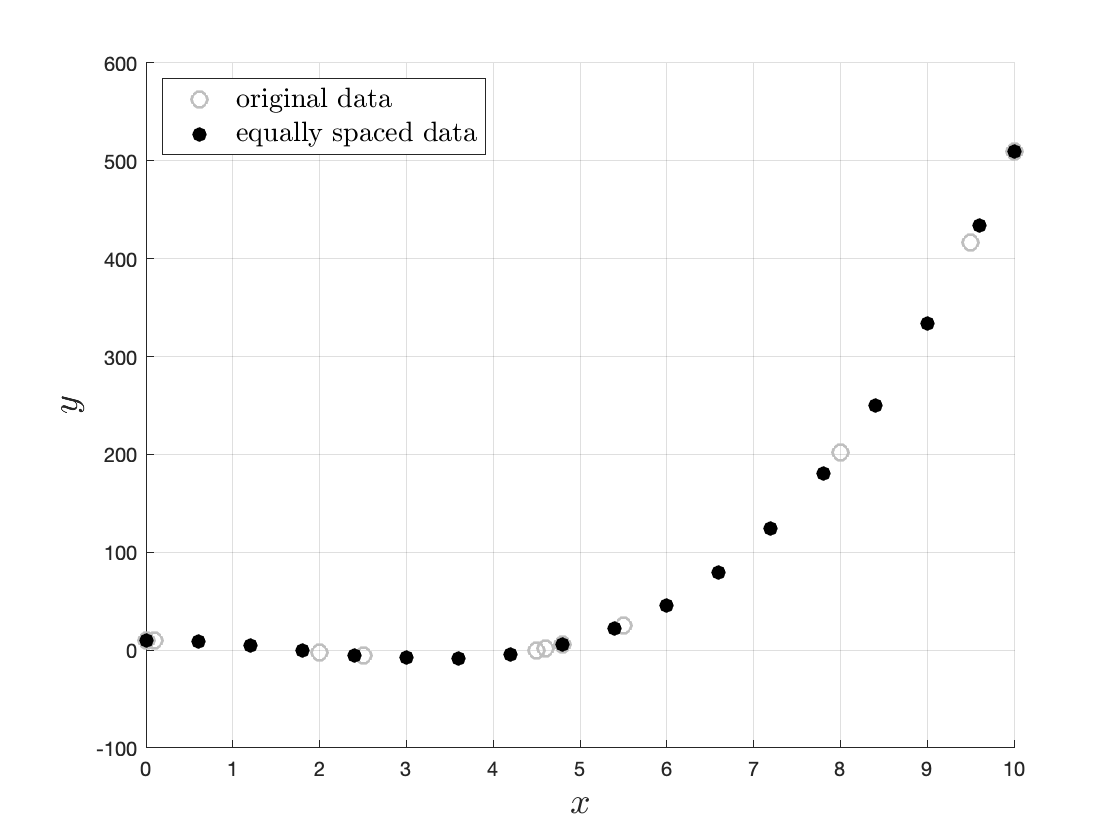

figure;
hold on;
plot(x,y,'o','MarkerSize',8,'LineWidth',1.5,'Color',[0.75,0.75,0.75]);
plot(x_new,y_new,'k.','MarkerSize',25,'LineWidth',1.5);
grid on;
hold off;
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
legend('original data','equally spaced data','Interpreter','latex',...
    'FontSize',14,'Location','northwest');